clear; % Clear any existing variables
close all;

% Load the dataset
fpath = fullfile(pwd, 'wine_quality_dataset_raw.csv');                         % File path
fname = readtable(fpath, 'VariableNamingRule', 'preserve');      % Correct read file

% Normalize the data
X = fname{:, 1:11};                  % Features (first 11 columns)
Y = fname{:, 12};                    % Quality rating (12th column)
X = (X - min(X)) ./ (max(X) - min(X));  % Min-Max normalization

% Convert labels to categorical format
Y_categorical = categorical(Y); % Keep this as categorical for training

% Split the Data into Training and Test Sets
cv = cvpartition(size(X, 1), 'HoldOut', 0.2);
X_train = X(training(cv), :);
Y_train = Y_categorical(training(cv)); % Use categorical labels directly
X_test = X(test(cv), :);
Y_test = Y_categorical(test(cv)); % Use categorical labels directly

% Data Augmentation (Placeholder)
% You can implement SMOTE or other techniques here to augment the minority classes
% For example, you can use the 'smote' function from a library if available

% Compute weight for class
classCounts = countcats(Y_categorical);
totalSamples = sum(classCounts);
classWeights = totalSamples ./ classCounts;  % Inverse frequency

% Normalize class weights to sum to 1
classWeights = classWeights / sum(classWeights);

% Create a layer graph
layers = [
    featureInputLayer(11)               % Input layer
    fullyConnectedLayer(12)              % Hidden layer
    dropoutLayer(0.5)                    % Dropout layer
    fullyConnectedLayer(numel(unique(Y_categorical))) % Output layer
    softmaxLayer                          % Softmax layer
    classificationLayer                  % Classification layer
];

lgraph = layerGraph(layers);

% Create and Train the Network
options = trainingOptions('adam', ...
    'MaxEpochs', 100, ...
    'Shuffle', 'every-epoch', ...
    'Verbose', false, ...
    'Plots', 'training-progress', ...
    'MiniBatchSize', 32); % Removed ClassWeights

% Train the network
net = trainNetwork(X_train, Y_train, lgraph, options); % Use Y_train as categorical

% Test the Network
Y_pred = classify(net, X_test);
Y_true_class = Y_test; % Use categorical labels directly

% Calculate Precision, Recall, F1-score
confMat = confusionmat(Y_true_class, Y_pred);
numClasses = size(confMat, 1);
precision = zeros(numClasses, 1);
recall = zeros(numClasses, 1);
f1 = zeros(numClasses, 1);

for i = 1:numClasses
    TP = confMat(i, i);
    FP = sum(confMat(:, i)) - TP;
    FN = sum(confMat(i, :)) - TP;
    precision(i) = TP / (TP + FP + eps);
    recall(i) = TP / (TP + FN + eps);
    f1(i) = 2 * (precision(i) * recall(i)) / (precision(i) + recall(i) + eps);
end

disp('Class | Precision | Recall | F1-score');

Class | Precision | Recall | F1-score


for i = 1:numClasses
    fprintf('  %2d   |   %.2f    | %.2f   |  %.2f\n', i, precision(i), recall(i), f1(i));
end

   1   |   0.00    | 0.00   |  0.00
   2   |   1.00    | 0.01   |  0.02
   3   |   0.47    | 0.50   |  0.49
   4   |   0.39    | 0.81   |  0.53
   5   |   0.67    | 0.01   |  0.02
   6   |   0.00    | 0.00   |  0.00
   7   |   0.00    | 0.00   |  0.00



macroPrecision = mean(precision);
macroRecall = mean(recall);
macroF1 = mean(f1);

fprintf('\nMacro-avg Precision: %.2f\n', macroPrecision);


Macro-avg Precision: 0.36


fprintf('Macro-avg Recall: %.2f\n', macroRecall);

Macro-avg Recall: 0.19


fprintf('Macro-avg F1-score: %.2f\n', macroF1);

Macro-avg F1-score: 0.15



% Evaluation of classification quality
accuracy = sum(Y_pred == Y_true_class) / length(Y_true_class);
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 41.41%


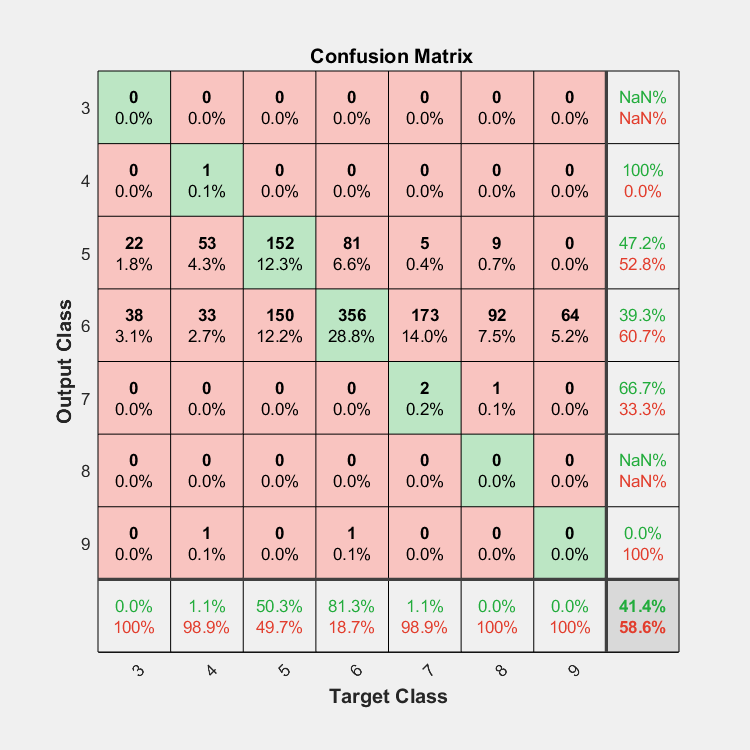


% Confusion Matrix
figure;
plotconfusion(Y_test, Y_pred);
classLabels = {'3','4','5','6','7','8','9',' '};

% Zmień etykiety osi
ax = gca;
ax.XTickLabel = classLabels;
ax.YTickLabel = classLabels;

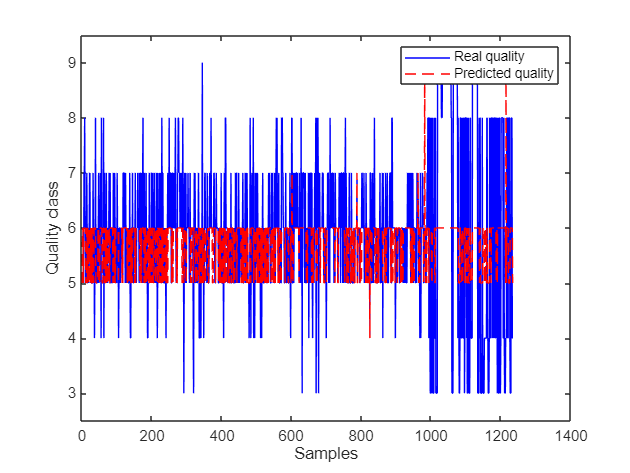

% Comparison of actual and predicted classes
figure;
plot(Y_true_class, 'b'); hold on;
plot(Y_pred, 'r--');
legend('Real quality', 'Predicted quality');
xlabel('Samples');
ylabel('Quality class');